# **Controlador On-Off: Modelo de Hovorka**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

En este script se implementa un controlador On/Off para el modelo Hovorka.

Se simula un escenario de 24 horas con resolución de 1 minuto, 3 ingestas de comida.

El controlador se enciende (On) cuando se supera el umbral de 180 mg/dL y se apaga por debajo de el (Off), se inyecta una cantidad fija de insulina que trata de mantener la referencia. se implementa ademas histeresis en el controlador para evitar el switcheo rapido. Finalmente se evaluan metricas clinicas (TIR, tiempo en hiperglucemia, tiempo en hipoglucemia, coeficiente de variación) y ademas se evaluan metricas clasicas de control (IAE, ISE, ITAE)

clear variables; close all; clc;

function main()
    params = initialize_parameters();% Parámetros del modelo
    y0 = initialize_state(params);% Condiciones iniciales
    [tspan, meal_times, meal_amounts] = simulation_setup();   % Configuración de simulación
    [t, y] = solve_system(tspan, y0, meal_times, meal_amounts, params);% Resolver el sistema
    results = process_results(t, y, meal_times, meal_amounts, params);% Procesar resultados
    plot_results(results, meal_times);% Visualizar resultados
end

Esta función define los parámetros fisiológicos del modelo de Hovorka. Incluye constantes relacionadas con la cinética de la insulina, la absorción de glucosa, la producción hepática endógena y el volumen de distribución. Son valores característicos del paciente necesarios para simular con realismo la dinámica glucosa-insulina.

function params = initialize_parameters()
    params.k12 = 0.066;
    params.ka1 = 0.006;
    params.ka2 = 0.06;
    params.ka3 = 0.03;
    params.ke = 0.138;
    params.VI = 0.12;
    params.VG = 0.16;
    params.AG = 0.8;
    params.t_maxG = 40;
    params.kb1 = 51.2e-4;
    params.kb2 = 8.2e-4;
    params.kb3 = 520e-4;
    params.EGP0 = 0.0161;
    params.F01 = 0.0097;
    params.t_maxI = 55;
end

Aquí se establecen las condiciones iniciales del sistema. Se configura la cantidad de glucosa en el plasma, los compartimentos de insulina subcutánea, la insulina plasmática y los estados de acción insulínica, partiendo de una condición basal estable.

function y0 = initialize_state(params)
    G0_mmol_L = 6;
    I0 = 0;
    y0 = [params.VG * G0_mmol_L;1;0;0;I0;0;0;0];
end

Esta sección define el intervalo total de simulación (24 horas) y configura las comidas del paciente. Se especifican los horarios en minutos y la cantidad de carbohidratos ingeridos en cada comida, lo cual afecta la dinámica de absorción de glucosa.

function [tspan, meal_times, meal_amounts] = simulation_setup()
    tspan = [0 1440];
    meal_times = [480, 720, 1200];
    meal_amounts = [35, 50, 45];
    %meal_amounts = [0, 0, 0];
end

En esta parte se resuelve el sistema de ecuaciones diferenciales del modelo utilizando el integrador numérico `ode45`. Se integran las dinámicas del modelo a lo largo del tiempo definido, considerando las condiciones iniciales y la respuesta a las comidas.

function [t, y] = solve_system(tspan, y0, meal_times, meal_amounts, params)
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
    [t, y] = ode45(@(t,y) model_equations(t, y, meal_times, meal_amounts, params),tspan, y0, options);
end

Esta función define las ecuaciones diferenciales que rigen el modelo de Hovorka. Incluye la absorción de glucosa e insulina, el control on-off basado en niveles de glucosa, la acción insulínica y las dinámicas de la glucosa plasmática. Es el núcleo del modelo.

function dy = model_equations(t, y, meal_times, meal_amounts, params)
    Q = y(1:2);
    S = y(3:4);
    I = y(5);
    x = y(6:8);

    U_G = calculate_glucose_absorption(t, meal_times, meal_amounts, params);

    % Control On-Off basado en glucosa
    G_mgdL = (Q(1) / params.VG) * 18.0156;
    upper_threshold = 180;
    lower_threshold = 70;

    if G_mgdL > upper_threshold
        insulin_rate = 0.3; % U/min
    elseif G_mgdL < lower_threshold
        insulin_rate = 0;
    else
        insulin_rate = 0; % zona muerta
    end

    [dS, U_I] = insulin_absorption_dynamics(S, insulin_rate, params);
    dI = plasma_insulin_dynamics(I, U_I, params);
    dx = insulin_action_dynamics(x, I, params);
    dQ = glucose_dynamics(Q, x, U_G, params);

    dy = [dQ; dS; dI; dx];
end

Calcula la tasa de absorción de glucosa intestinal a partir de las comidas programadas. Se utiliza una función dependiente del tiempo transcurrido desde cada comida, con base en una absorción exponencial.

function U_G = calculate_glucose_absorption(t, meal_times, meal_amounts, params)
    U_G = 0;
    for i = 1:length(meal_times)
        if t >= meal_times(i)
            dt = t - meal_times(i);
            U_G = U_G + (meal_amounts(i) * params.AG * dt * exp(-dt/params.t_maxG)) / (params.t_maxG^2);
        end
    end
end

Modela la absorción de insulina subcutánea desde el sitio de inyección hacia el plasma. Se representa mediante un sistema de dos compartimentos, considerando el retardo fisiológico de absorción.

function [dS, U_I] = insulin_absorption_dynamics(S, rate, params)
    dS1 = rate - S(1)/params.t_maxI;
    dS2 = S(1)/params.t_maxI - S(2)/params.t_maxI;
    U_I = S(2)/params.t_maxI;
    dS = [dS1; dS2];
end

Simula el comportamiento de la insulina en plasma, considerando la tasa de aparición desde los compartimentos subcutáneos y su degradación por aclaramiento fisiológico.

function dI = plasma_insulin_dynamics(I, U_I, params)
    dI = U_I/params.VI - params.ke*I;
end

Define la acción de la insulina en tres frentes: supresión de la producción hepática, mejora de la captación muscular y aumento de la captación por otros tejidos. Estas acciones dependen de la concentración plasmática de insulina.

function dx = insulin_action_dynamics(x, I, params)
    dx1 = -params.ka1*x(1) + params.kb1*I;
    dx2 = -params.ka2*x(2) + params.kb2*I;
    dx3 = -params.ka3*x(3) + params.kb3*I;
    dx = [dx1; dx2; dx3];
end

Representa la dinámica de la glucosa en dos compartimentos (accesible y no accesible). Incluye la producción hepática, la utilización dependiente e independiente de insulina, el efecto renal y la absorción de glucosa desde el intestino.

function dQ = glucose_dynamics(Q, x, U_G, params)
    G = Q(1)/params.VG;

    % Flujo no dependiente de insulina 
    if G >= 4.5
        F01c = params.F01;
    else
        F01c = params.F01 * G / 4.5;
    end

    % Clearance renal
    if G >= 9
        FR = 0.003 * (G - 9) * params.VG;
    else
        FR = 0;
    end

    dQ1 = -(F01c/(params.VG*G) + x(1))*Q(1) + params.k12*Q(2) - FR + U_G + params.EGP0*(1 - x(3));
    dQ2 = x(1)*Q(1) - (params.k12 + x(2))*Q(2);
    dQ = [dQ1; dQ2];
end

Procesa los resultados obtenidos tras la simulación. Convierte las unidades fisiológicas, calcula las acciones de insulina y glucosa, evalúa la insulina aplicada por el controlador, y obtiene métricas de desempeño como tiempo en rango, hipoglucemia, hiperglucemia, coeficiente de variación e índices IAE, ISE e ITAE.

function results = process_results(t, y, meal_times, meal_amounts, params)
    results.t = t;
    results.y = y;

    results.G = (y(:,1) / params.VG) * 18.0156;% Glucosa en mg/dL
    results.I = y(:,5) * 0.1; % Insulina en mU/dL

    results.x1 = y(:,6);
    results.x2 = y(:,7);% Acciones de la insulina
    results.x3 = y(:,8);

    results.U_I = y(:,4) / params.t_maxI;% Tasa de aparición de insulina

    % Absorción de glucosa intestinal
    results.U_G = zeros(size(t));
    for i = 1:length(meal_times)
        for j = 1:length(t)
            if t(j) >= meal_times(i)
                dt = t(j) - meal_times(i);
                results.U_G(j) = results.U_G(j) + ...
                    (meal_amounts(i) * params.AG * dt * exp(-dt / params.t_maxG)) / (params.t_maxG^2);
            end
        end
    end

    % Estado del controlador
        % Insulina aplicada por el controlador On-Off (U/min)
    upper_threshold = 180; % mg/dL
    lower_threshold = 70;  % mg/dL
    insulin_rate_applied = zeros(size(results.G));

    for k = 1:length(results.G)
        if results.G(k) > upper_threshold
            insulin_rate_applied(k) = 0.3;
        elseif results.G(k) < lower_threshold
            insulin_rate_applied(k) = 0;
        else
            insulin_rate_applied(k) = 0.0; % zona muerta
        end
    end

    results.insulin_applied = insulin_rate_applied;
    results.G_ref = zeros(size(results.t));
    for i = 1:length(results.t)
        results.G_ref(i) = smooth_glucose_reference(results.t(i));
    end
        % === MÉTRICAS DE TIEMPO EN RANGO E HIPER/HIPOGLUCEMIA ===
    total_time = results.t(end) - results.t(1); % en minutos
    in_range = (results.G >= 70) & (results.G <= 180);
    hypo = results.G < 70;
    hyper = results.G > 180;
    dt = [diff(results.t); 0];
    results.time_in_range = sum(dt .* in_range);      % minutos
    results.time_hypo = sum(dt .* hypo);
    results.time_hyper = sum(dt .* hyper);
    results.percent_in_range = 100 * results.time_in_range / total_time;
    results.percent_hypo = 100 * results.time_hypo / total_time;
    results.percent_hyper = 100 * results.time_hyper / total_time;

    % === COEFICIENTE DE VARIACIÓN ===
    results.mean_glucose = mean(results.G);
    results.std_glucose = std(results.G);
    results.cv_glucose = 100 * results.std_glucose / results.mean_glucose;

    % === ÍNDICES DE DESEMPEÑO (IAE, ISE, ITAE) ===
    error = results.G - results.G_ref;
    results.IAE = trapz(results.t, abs(error));
    results.ISE = trapz(results.t, error.^2);
    results.ITAE = trapz(results.t, results.t .* abs(error));

    % Mostrar en consola
    fprintf('\n--- ÍNDICES DE DESEMPEÑO ---\n');
    fprintf('IAE  = %.2f\n', results.IAE);
    fprintf('ISE  = %.2f\n', results.ISE);
    fprintf('ITAE = %.2f\n', results.ITAE);
    fprintf('\n--- MÉTRICAS DE TIEMPO ---\n');
    fprintf('Tiempo en rango: %.2f%%\n', results.percent_in_range);
    fprintf('Tiempo en hipoglucemia: %.2f%%\n', results.percent_hypo);
    fprintf('Tiempo en hiperglucemia: %.2f%%\n', results.percent_hyper);
    fprintf('Coeficiente de variación: %.2f%%\n', results.cv_glucose);
end

Genera las gráficas que permiten visualizar el comportamiento del sistema. Incluye glucosa plasmática, insulina, insulina aplicada, tasas de absorción, acciones insulínicas, masas de glucosa y un resumen en forma de gráfico de barras con métricas de control.

function plot_results(results, meal_times)
    figure('Position', [100, 100, 1200, 1000]);
    t_hours = results.t / 60;
    meal_hours = meal_times / 60;

    % 1. Glucosa plasmática
    subplot(4,2,1);
    h1 = plot(t_hours, results.G, 'b', 'LineWidth', 2); hold on;
    plot(t_hours, results.G_ref, '--k', 'LineWidth', 1.5); 
    h2 = gobjects(length(meal_hours),1);
    for i = 1:length(meal_hours)
        h2(i) = xline(meal_hours(i), '--g', 'LineWidth', 2);
    end
    yline(70, '--r', 'LineWidth', 1.2, 'Alpha', 0.7);
    yline(180, '--r', 'LineWidth', 1.2, 'Alpha', 0.7);
    text(0.5, 75, '← Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
    text(0.5, 185, 'Hiperglucemia →', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');
    title('Glucosa plasmática');
    xlabel('Tiempo (horas)');
    ylabel('Glucosa (mg/dL)');
    xlim([0 24]);
    grid on;
    legend([h1, h2(1)], {'Glucosa', 'Comidas'}); % Solo estas dos

    % 2. Insulina plasmática
    subplot(4,2,2);
    plot(t_hours, results.I, 'r', 'LineWidth', 2);
    title('Insulina plasmática');
    xlabel('Tiempo (horas)');
    ylabel('Insulina (mU/dL)');
    legend('Insulina');
    xlim([0 24]);
    grid on;

    % 3. Estado del controlador On-Off (debajo de glucosa)
    subplot(4,2,3);
    stairs(t_hours, results.insulin_applied, 'k', 'LineWidth', 2);
    ylim([0 0.35]); xlim([0 24]);
    title('Insulina aplicada por el controlador');
    xlabel('Tiempo (horas)');
    ylabel('U/min');
    grid on;


    % 4. Tasa de aparición de insulina
    subplot(4,2,4);
    plot(t_hours, results.U_I, 'c', 'LineWidth', 2);
    title('Tasa de aparición de insulina');
    xlabel('Tiempo (horas)');
    ylabel('U/min');
    legend('U_I');
    xlim([0 24]);
    grid on;

    % 5. Acciones de la insulina
    subplot(4,2,5);
    plot(t_hours, results.x1, 'g', t_hours, results.x2, 'b', t_hours, results.x3, 'm', 'LineWidth', 2);
    title('Acciones de la insulina');
    xlabel('Tiempo (horas)');
    ylabel('Acción (adimensional)');
    legend('x_1', 'x_2', 'x_3');
    xlim([0 24]);
    grid on;

    % 6. Absorción de glucosa intestinal
    subplot(4,2,6);
    plot(t_hours, results.U_G, 'k', 'LineWidth', 2);
    title('Absorción de glucosa intestinal');
    xlabel('Tiempo (horas)');
    ylabel('mmol/kg/min');
    legend('U_G');
    xlim([0 24]);
    grid on;

    % 7. Masas de glucosa Q1 y Q2
    subplot(4,2,7);
    plot(t_hours, results.y(:,1), 'b', t_hours, results.y(:,2), 'r', 'LineWidth', 2);
    title('Masas de glucosa en compartimentos');
    xlabel('Tiempo (horas)');
    ylabel('Masa (mmol/kg)');
    legend('Q_1 (accesible)', 'Q_2 (no accesible)');
    xlim([0 24]);
    grid on;
      
    % 8. Métricas de tiempo y variabilidad
    subplot(4,2,8);
    metric_values = [results.percent_in_range, results.percent_hypo, ...
                     results.percent_hyper, results.cv_glucose];
    metric_labels = {'TIR (%)', 'Hipo (%)', 'Hiper (%)', 'CV (%)'};
    bar_colors = [0 0.8 0; 1 0 0; 1 0.5 0; 0 0 1];

    b = bar(metric_values, 'FaceColor', 'flat');
    for i = 1:length(metric_values)
        b.CData(i,:) = bar_colors(i,:);
        text(i, metric_values(i) + 3, sprintf('%.1f', metric_values(i)), ...
            'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
    set(gca, 'XTickLabel', metric_labels, 'XTick', 1:4);
    ylim([0 110]);
    ylabel('Porcentaje / Valor');
    title('Métricas de Control');
    grid on;

end

function ref_val = smooth_glucose_reference(t_min)
    t_hour = mod(t_min / 60, 24); 
    %funciones sigmoideas
    if t_hour >= 0 && t_hour < 6
        ref_val = 100;
    elseif t_hour >= 6 && t_hour < 8
        alpha = (t_hour - 6) / 2; % 0 a 1 en 2 horas
        ref_val = 100 + (140 - 100) * (3*alpha^2 - 2*alpha^3); % 
    elseif t_hour >= 8 && t_hour < 12
        ref_val = 140;
    elseif t_hour >= 12 && t_hour < 14 % Transición gradual
        alpha = (t_hour - 12) / 2;
        ref_val = 140 + (130 - 140) * (3*alpha^2 - 2*alpha^3);
    elseif t_hour >= 14 && t_hour < 20
        ref_val = 130;
    elseif t_hour >= 20 && t_hour < 22 % Transición gradual
        alpha = (t_hour - 20) / 2;
        ref_val = 130 + (105 - 130) * (3*alpha^2 - 2*alpha^3);
    else % 22 a 24
        ref_val = 105;
    end
end


--- ÍNDICES DE DESEMPEÑO ---
IAE  = 125856.60
ISE  = 13324667.63
ITAE = 79960087.53

--- MÉTRICAS DE TIEMPO ---
Tiempo en rango: 19.82%
Tiempo en hipoglucemia: 72.12%
Tiempo en hiperglucemia: 8.07%
Coeficiente de variación: 138.81%


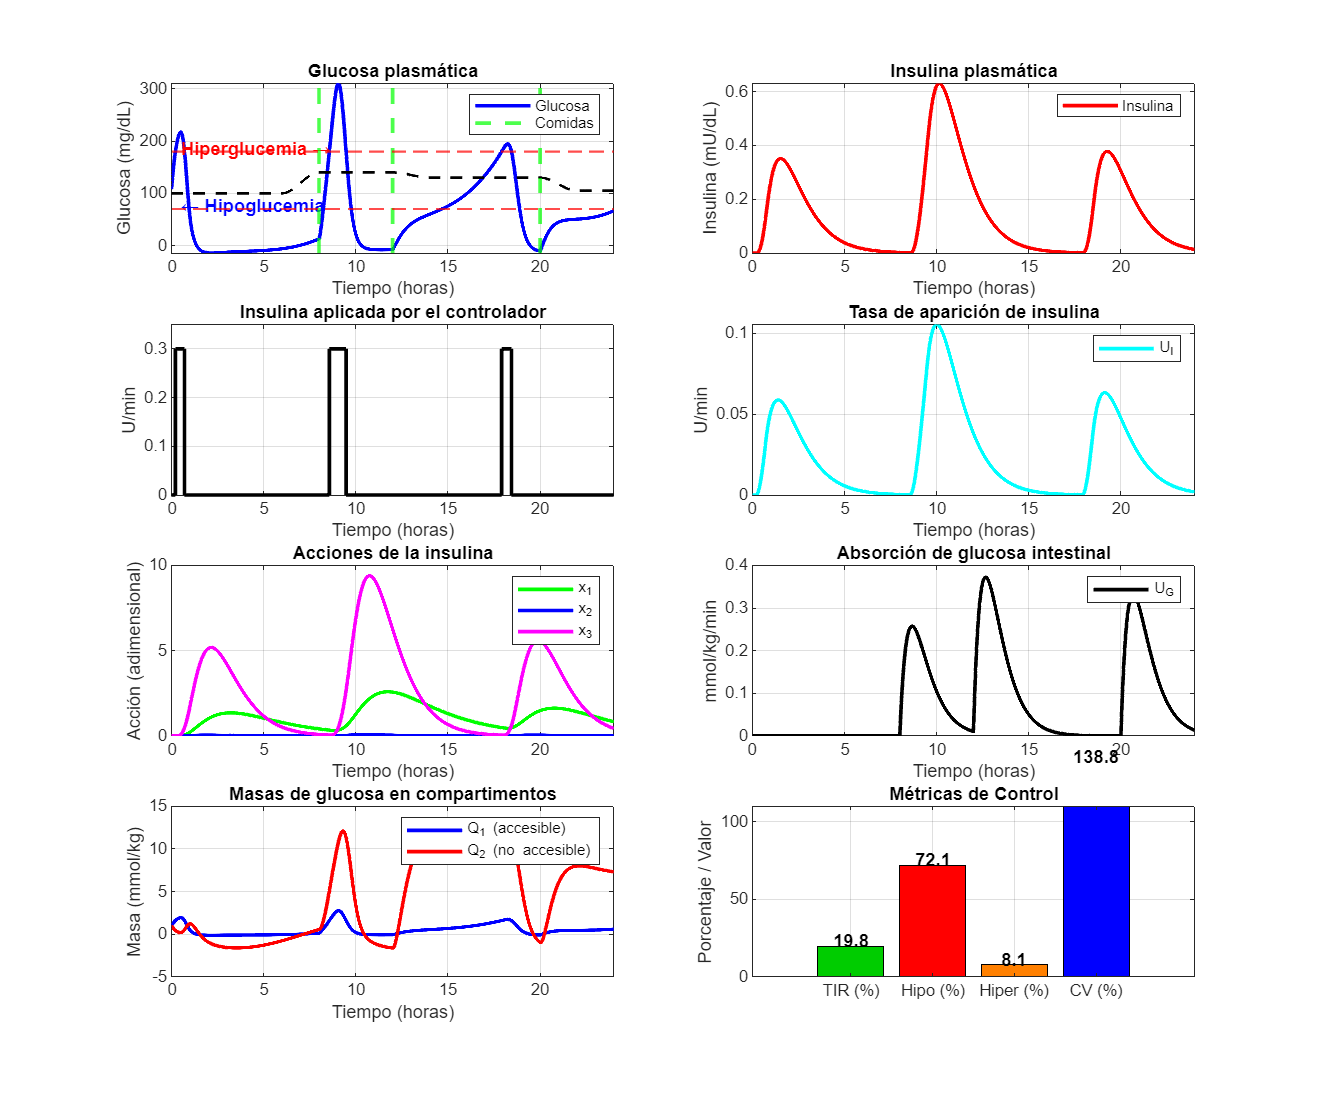

main;

La evolución de la glucosa plasmática a lo largo de las 24 horas revela fluctuaciones marcadas tras la ingesta de alimentos, siendo más notoria la hipoglucemia posprandial. Aunque el controlador On-Off actúa correctamente cuando se supera el umbral establecido, no logra prevenir una hipoglucemia significativa en las horas posteriores, lo que evidencia una respuesta aún imprecisa en el control fino de los niveles de glucosa.

Por su parte, la insulina plasmática muestra incrementos claros y sostenidos tras cada activación del controlador, reflejando la absorción retardada típica de la vía subcutánea. Esta dinámica se ve reforzada por la tasa de aparición de insulina, que manifiesta picos suaves pero prolongados, explicando por qué persisten los efectos hipoglucemiantes incluso después de interrumpir la administración.

La gráfica de insulina aplicada por el controlador confirma un comportamiento intermitente, activándose únicamente ante episodios hiperglucémicos. Si bien este patrón evita la administración continua innecesaria, su acción puntual no logra compensar el retardo farmacodinámico, derivando en hipoglucemias subsiguientes.

Las acciones de la insulina (x₁, x₂ y x₃) muestran una respuesta coherente con los picos plasmáticos, siendo la inhibición de la producción hepática de glucosa (x₃) la más dominante. Esta acción juega un papel crucial en la reducción postpandrial de la glucosa, aunque también puede contribuir al descenso excesivo si no se regula adecuadamente.

La absorción intestinal de glucosa presenta una forma fisiológicamente válida, con picos bien definidos tras cada comida, lo que valida la correcta implementación del estímulo externo. En paralelo, las masas de glucosa en los compartimentos accesible (Q₁) y no accesible (Q₂) evidencian el tránsito y almacenamiento transitorio de glucosa en el organismo, con Q₂ actuando como un reservorio que amortigua las fluctuaciones.

Finalmente, las métricas de control refuerzan las limitaciones observadas: el tiempo en rango es bajo (19.8%), mientras que el 72.1% del tiempo se mantiene en hipoglucemia, una condición clínica no deseada. Aunque se controla en parte la hiperglucemia (8.1%), el elevado coeficiente de variación (138.8%) indica una alta inestabilidad en los niveles de glucosa, lo que sugiere la necesidad de ajustar o rediseñar el controlador.